# Exercicis - AC5

La sessió de dimarts 12 de març i dimecres 13 de març tindrà el contingut següent:

- Dos exercicis de repàs de mètodes iteratius

- Estudi de l'ordre de convergència

- Sistemes d'equacions no lineals

EXERCICI 3 - LAB3.pdf

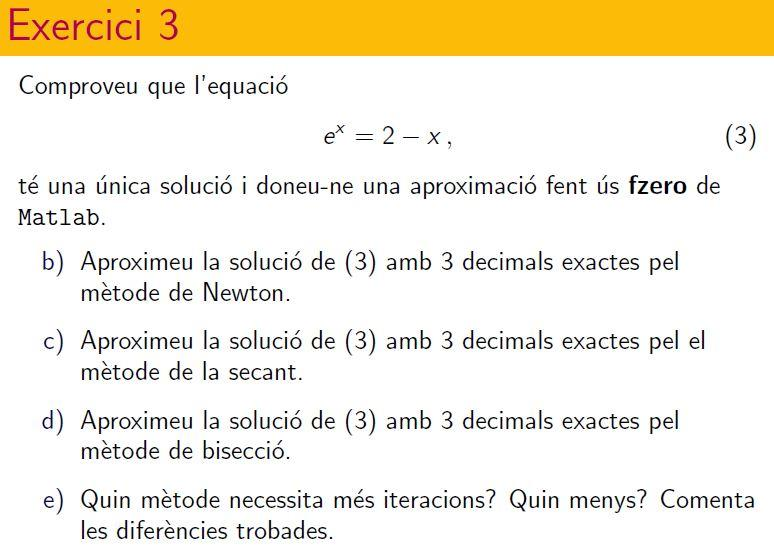

% Bolzano para determinar rango (a,b)
f = @(x)2-x-exp(x);
x = 0.2:0.05:0.6;
[x', f(x)']

ans =     0.2000    0.5786
    0.2500    0.4660
    0.3000    0.3501
    0.3500    0.2309
    0.4000    0.1082
    0.4500   -0.0183
    0.5000   -0.1487
    0.5500   -0.2833
    0.6000   -0.4221


a = 0.4;
b = 0.8;
tol = 0.0005;
nmax = 10;
% (0.4, 0.8)

NEWTON

df = @(x)-1-exp(x);
[zero_n, tolf_n, niter_n] = newton(f ,df ,a ,tol, nmax)

 El metodo convergio en la iteracion 

zero_n = 0.4429

tolf_n = 6.6613e-15

niter_n = 3

SECANT

[zero_s, res_s, niter_s] = secante(f, a, b, tol, nmax)

zero_s = 0.4429

res_s = -1.8726e-06

niter_s = 3

BISECCIO

[zero_b, res_b, niter_b] = bisection(f, a, b, tol, nmax)

zero_b = 0.4426

res_b = 7.0642e-04

niter_b = 9

EXERCICI 4 - LAB4.pdf

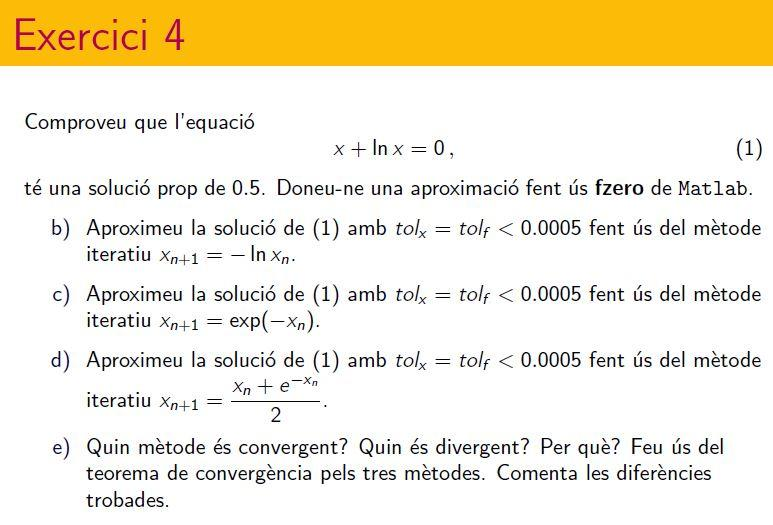

GRAFICA

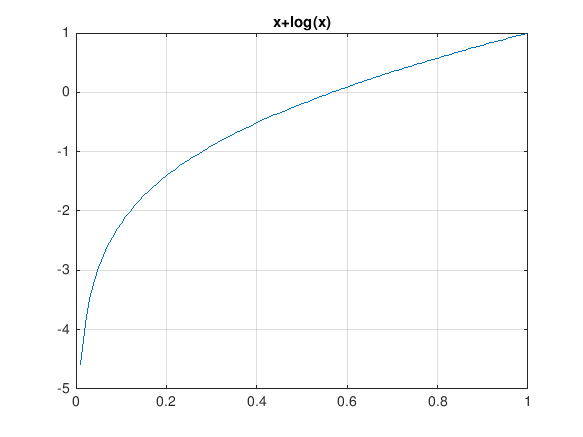

f = @(x)x+log(x);
t = 0.01:0.01:1;
plot(t, f(t)), grid, title('x+log(x)')

FZERO

f=@(x)x+log(x);
x0 = [0.5 0.6];
options = optimset('Display', 'iter');
[x fval exitflag output] = fzero(f, x0, options)

 
 Func-count    x          f(x)             Procedure
    2             0.6     0.0891744        initial
    3        0.568414    0.00350846        interpolation
    4        0.567143    1.9575e-07        interpolation
    5        0.567143   3.75366e-13        interpolation
    6        0.567143  -1.11022e-16        interpolation
    7        0.567143  -1.11022e-16        interpolation
 
Zero found in the interval [0.5, 0.6]


x =       0.56714


fval =   -1.1102e-16


exitflag =      1


output = struct with fields:
    intervaliterations: 0
            iterations: 5
             funcCount: 7
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [0.5, 0.6]'


ESTUDI DE CONVERGERNCIA A PRIORI

syms x; dg1(x) = diff(-log(x), x)

$$dg1(x) = -\frac{1}{x}$$

syms x; dg2(x) = diff(exp(-x), x)

$$dg2(x) = -{\mathrm{e}}^{-x}$$

syms x; dg3(x) = diff((x+exp(-x))/2, x)

$$dg3(x) = \frac{1}{2}-\frac{{\mathrm{e}}^{-x}}{2}$$

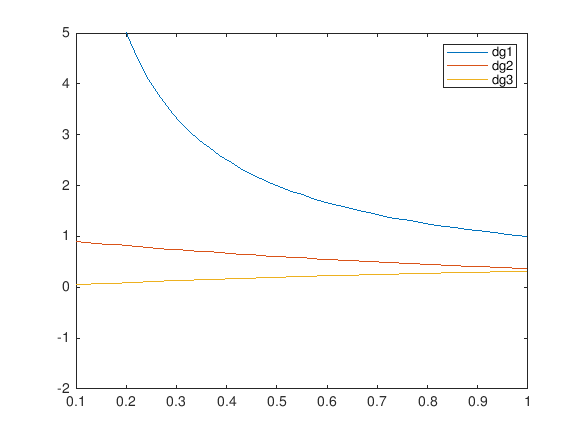

fplot({abs(dg1), abs(dg2), abs(dg3)}, [0.1, 1])
legend('dg1', 'dg2', 'dg3')
xlim([0.1 1])
ylim([-2 5])

taula = [vpa(dg1(0.5)), vpa(dg2(0.5), 4), vpa(dg3(0.5), 4)]

$$taula = \left(\begin{array}{ccc} -2.0 & -0.60653065971200703643262386322021 & 0.19673467014399648178368806838989 \end{array}\right)$$

% l'ultima funcio (dg3) te un valor major, per tant la convergencia es mes
% rapida

% metode iteratiu, calcular zero de f(x) amb l'ajuda de g(x)
a = 0.4; b = 0.6; tol = 0.0005; nmax = 15 ;
g = @(x)-log(x);
x = a+0.5*(b-a);
k = 0;
tolx = 1; tolf = 1;
R = [k, x, tolf, tolx];
while (tolx > tol) && (tolf > tol) && (k < nmax)
    y = g(x);
    tolx = abs(y-x);
    tolf = abs(f(y));
    x = y;
    k = k+1;
    R = [R; k, x, tolf, tolx];
end
format short g
R

R =             0 +          0i          0.5 +          0i            1 +          0i            1 +          0i
            1 +          0i      0.69315 +          0i      0.32663 +          0i      0.19315 +          0i
            2 +          0i      0.36651 +          0i      0.63721 +          0i      0.32663 +          0i
            3 +          0i       1.0037 +          0i       1.0074 +          0i      0.63721 +          0i
            4 +          0i   -0.0037146 +          0i       6.4203 +          0i       1.0074 +          0i
            5 +          0i       5.5955 -     3.1416i       8.3015 +          0i       6.4203 +          0i
            6 +          0i       -1.859 +    0.51159i       3.5919 +          0i       8.3015 +          0i
            7 +          0i     -0.65652 -      2.873i       4.6877 +          0i       3.5919 +          0i
            8 +          0i      -1.0808 +     1.7955i        3.923 +          0i       4.6877 +          0i
            9 +

a = 0.4; b = 0.6; tol = 0.0005; nmax = 15 ;
g = @(x)exp(-x);
x = a+0.5*(b-a);
k = 0;
tolx = 1; tolf = 1;
R = [k, x, tolf, tolx];
while (tolx > tol) && (tolf > tol) && (k < nmax)
    y = g(x);
    tolx = abs(y-x);
    tolf = abs(f(y));
    x = y;
    k = k+1;
    R = [R; k, x, tolf, tolx];
end
format short g
R

R =             0          0.5            1            1
            1      0.60653      0.10653      0.10653
            2      0.54524     0.061291     0.061291
            3       0.5797     0.034464     0.034464
            4      0.56006     0.019638     0.019638
            5      0.57117     0.011108     0.011108
            6      0.56486    0.0063092    0.0063092
            7      0.56844    0.0035751    0.0035751
            8      0.56641    0.0020286    0.0020286
            9      0.56756    0.0011502    0.0011502


a = 0.4; b = 0.6; tol = 0.0005; nmax = 15 ;
g = @(x)(x+exp(-x))/2;
x = a+0.5*(b-a);
k = 0;
tolx = 1; tolf = 1;
R = [k, x, tolf, tolx];
while (tolx > tol) && (tolf > tol) && (k < nmax)
    y = g(x);
    tolx = abs(y-x);
    tolf = abs(f(y));
    x = y;
    k = k+1;
    R = [R; k, x, tolf, tolx];
end
format short g
R

R =             0          0.5            1            1
            1      0.55327     0.038652     0.053265
            2      0.56417    0.0082376     0.010902
            3       0.5665     0.001777    0.0023333
            4        0.567   0.00038433   0.00050379


%com hem dit, dg3 convergeix mes rapid que els altres, tan sols 4
%iteracions

EXERCICI 5 - LAB4.pdf

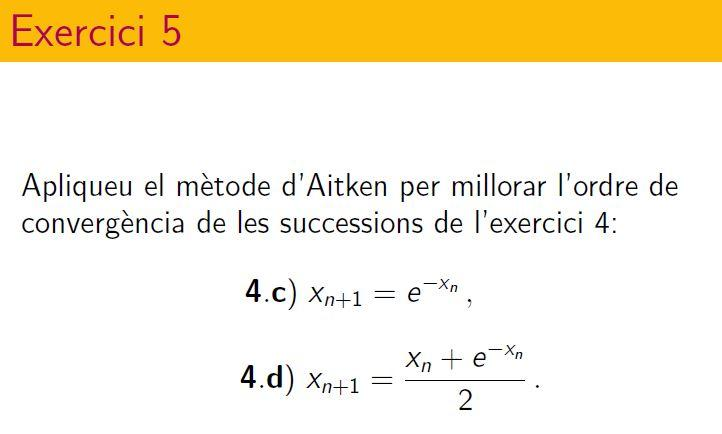

% acceleracio de la segona funcion d'abans amb Aiken
clearvars;
format long g
f = @(x)x+log(x);       %funcio
a = 0.4; b = 0.6; tol = 0.0005; nmax = 15 ;
g = @(x)exp(-x);        %iteratiu
x = a+0.5*(b-a);
k = 0;
tolx = 1; tolf = 1;
y(1) = x;               %Aiken
y(2) = g(y(1));
y(3) = g(y(2));
z(3) = (y(3)*y(1)-y(2)^2)/(y(3)-2*y(2)+y(1))

z =                          0                         0          0.56762387641092


for k = 3:10
    y(k+1) = g(y(k));
    z(k+1) = (y(k+1)*y(k-1)-y(k)^2)/(y(k+1)-2*y(k)+y(k-1));
end
R = [y', z']

R =                        0.5                         0
         0.606530659712633                         0
         0.545239211892605          0.56762387641092
         0.579703094878068          0.56729898932651
         0.560064627938902         0.567193142398219
         0.571172148977215         0.567159364489465
         0.564862946980323         0.567148453258233
         0.568438047570066         0.567144952370406
         0.566409452746921         0.567143824737764
         0.567559634262242         0.567143462321432


% R = [k, x, tolf, tolx];
% while (tolx > tol) && (tolf > tol) && (k < nmax)
%     y = g(x);
%     tolx = abs(y-x);
%     tolf = abs(f(y));
%     x = y;
%     k = k+1;
%     R = [R; k, x, tolf, tolx];
% end
% format short g
% R




EXERCICI 5 - LAB5.pdf

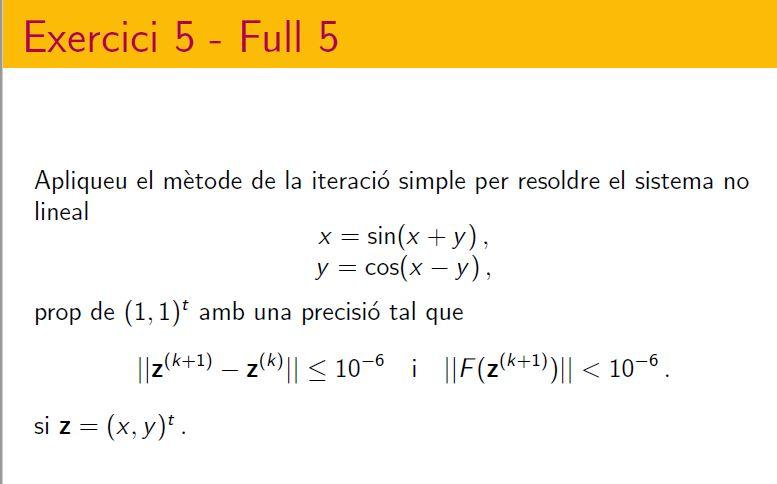

EXERCICI 6 - LAB5.pdf